Scale-free robustness demo: random failure vs targeted hub attack

Run this live script from the package folder so the helper functions are on the MATLAB path.

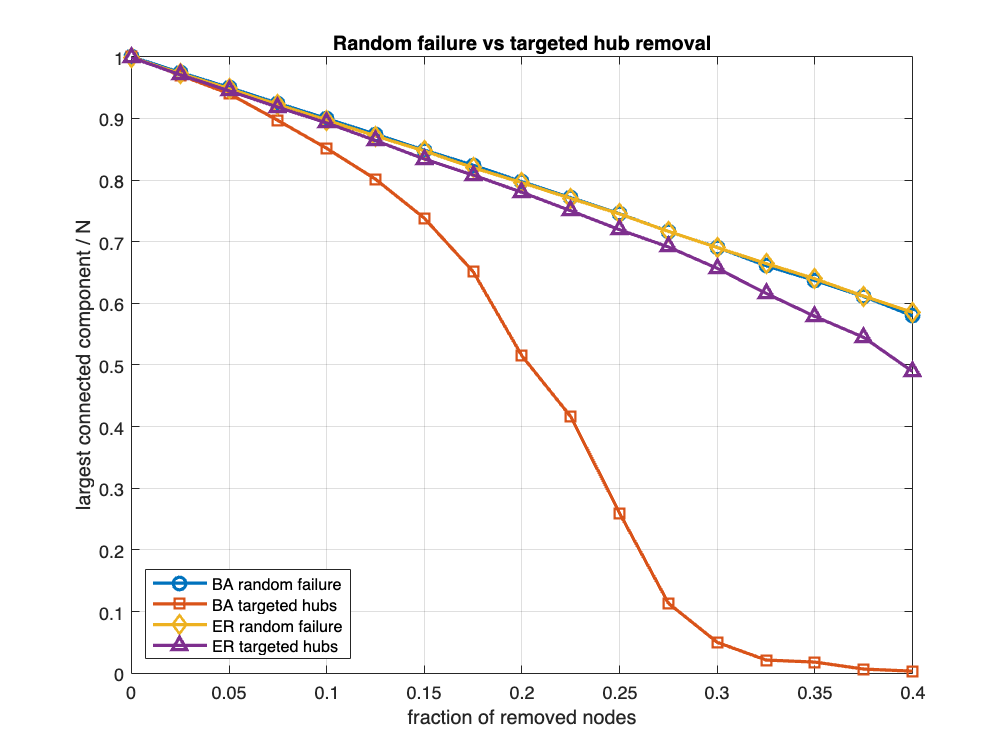

clearvars; close all; clc;

%DEMO_SCALEFREE_ROBUSTNESS Robustness to random failures vs targeted attack.
%
% Compares BA and ER graphs with approximately the same average degree.

rng(5);

n = 1500;
m0 = 5;
m = 3;                     % BA average degree ~ 2m = 6
kbar = 2 * m;

Gba = make_ba_graph(n, m0, m);
Ger = make_er_graph(n, kbar / (n - 1));

fractions = linspace(0, 0.40, 17);
numTrials = 6;

SbaRand = zeros(size(fractions));
SbaTarget = zeros(size(fractions));
SerRand = zeros(size(fractions));
SerTarget = zeros(size(fractions));

[~, ordBA] = sort(degree(Gba), 'descend');
[~, ordER] = sort(degree(Ger), 'descend');

for i = 1:numel(fractions)
    q = fractions(i);
    kRemove = round(q * n);

    if kRemove == 0
        remBA = [];
        remER = [];
    else
        remBA = ordBA(1:kRemove);
        remER = ordER(1:kRemove);
    end

    SbaTarget(i) = largest_component_fraction_after_removal(Gba, remBA);
    SerTarget(i) = largest_component_fraction_after_removal(Ger, remER);

    tmp = 0;
    for r = 1:numTrials
        tmp = tmp + largest_component_fraction_after_removal(Gba, randperm(n, kRemove));
    end
    SbaRand(i) = tmp / numTrials;

    tmp = 0;
    for r = 1:numTrials
        tmp = tmp + largest_component_fraction_after_removal(Ger, randperm(n, kRemove));
    end
    SerRand(i) = tmp / numTrials;
end

figure('Name', 'Scale-free robustness comparison');
plot(fractions, SbaRand, 'o-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold on;
plot(fractions, SbaTarget, 's-', 'LineWidth', 1.8, 'MarkerSize', 7);
plot(fractions, SerRand, 'd-', 'LineWidth', 1.8, 'MarkerSize', 7);
plot(fractions, SerTarget, '^-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold off;

xlabel('fraction of removed nodes');
ylabel('largest connected component / N');
title('Random failure vs targeted hub removal');
legend('BA random failure', 'BA targeted hubs', ...
       'ER random failure', 'ER targeted hubs', ...
       'Location', 'southwest');
grid on;


fprintf('\nScale-free robustness demo finished.\n');


Scale-free robustness demo finished.


fprintf('BA graphs are typically more robust to random failures than ER,\n');

BA graphs are typically more robust to random failures than ER,


fprintf('but much more fragile under targeted removal of hubs.\n\n');

but much more fragile under targeted removal of hubs.

